EXPERIMENT NO-3

Linear convolution

a)using built in function

clc;
clear all;
close all;
x=input("Enter the elements in x[n]:");
x_ind=input("Enter the index of x[n]:");
h=input("Enter the elements in h[n]:");
h_ind=input("Enter the index of h[n]:");
y=conv(x,h);
y_ind=min(x_ind)+min(h_ind):max(x_ind)+max(h_ind);
disp('Linear convolution result:');

Linear convolution result:


disp(y);

     1     3     4     5     4     2     1



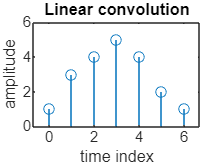

stem(y_ind,y);
title("Linear convolution");
xlabel("time index");
ylabel("amplitude");

b)without using built in function

x=input("Enter the elements in x[n]:");
x_ind=input("Enter the index of x[n]:");
h=input("Enter the elements in h[n]:");
h_ind=input("Enter the index of h[n]:");
n1 = length(x);
n2 = length(h);
n = n1 + n2 - 1;
y = zeros(1, n);
for i = 0:n-1
    for j = 0:n1-1
        if (i - j >= 0 && i - j < n2)
            y(i+1) = y(i+1) + x(j+1) * h(i - j + 1);
        end
    end
end
disp('Linear convolution result:');

Linear convolution result:


disp(y);

     1     3     4     5     4     2     1



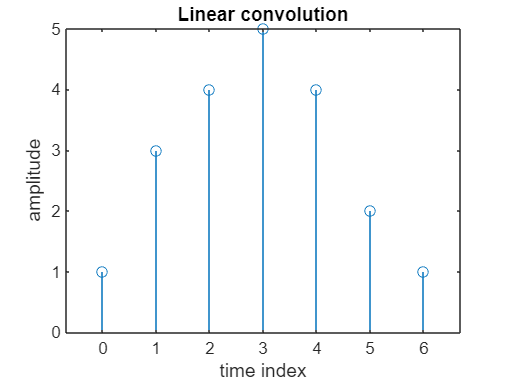

y_ind=min(x_ind)+min(h_ind):max(x_ind)+max(h_ind);
stem(y_ind,y);
title("Linear convolution");
xlabel("time index");
ylabel("amplitude");